# **Introductory script illustrating how to run an SVM classifier to measure discrimination performance between 2 stimuli.**

*This tutorial generates ISETBio scenes representing a test Gabor stimulus  and a null (zero contrast) stimulus. The stimuli are passed through human wavefront-based optics, and cone mosaic excitation responses are computed.*

# **Step 1.** Create a presentation display

We employ an existing display specification, here an Apple LCD display.


%% Create presentation display and place it 57 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

# **Step 2.** Create the test stimulus - a 10% contrast Gabor

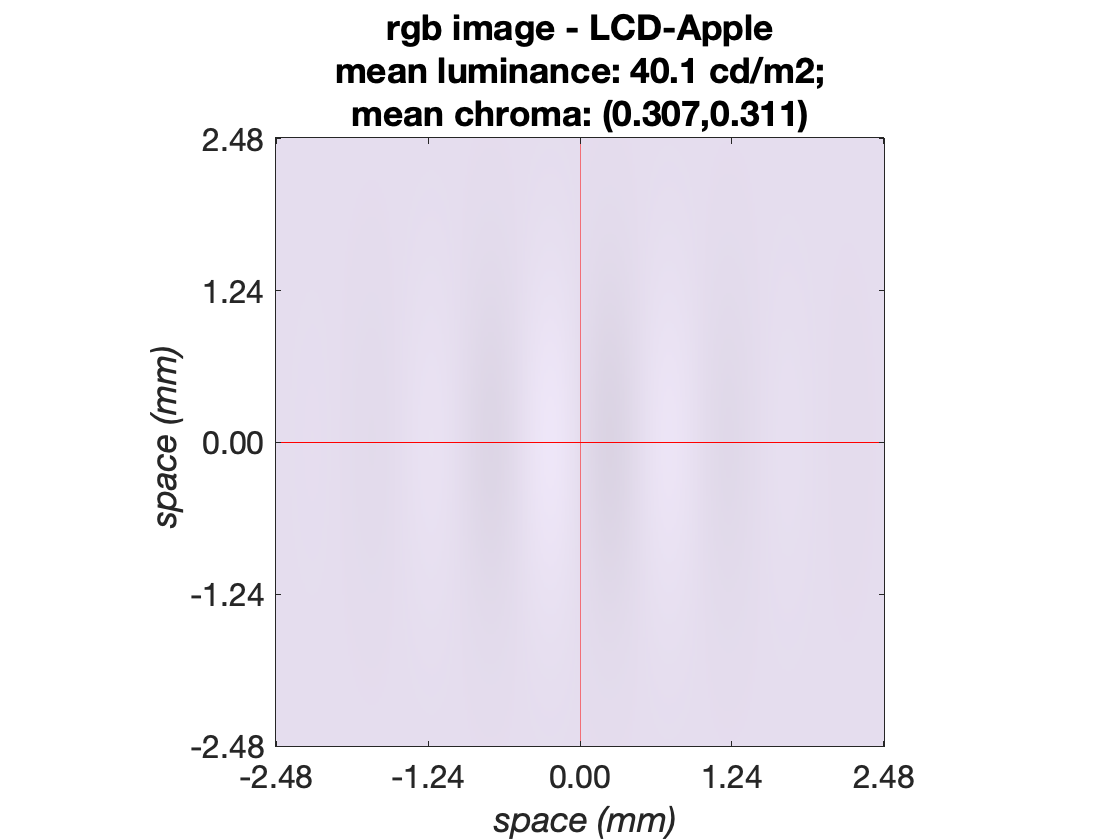

%% parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 10, ... % 5 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 90, ...                    % spatial phase in degrees
    'sizeDegs', 0.5, ...                    % 0.5 x 0.5 degrees
    'sigmaDegs', 0.3/3, ...                 % sigma of Gaussian envelope, in degrees
    'contrast', 0.1,...                     % Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

% Generate a scene representing the 10% Gabor stimulus as realized on the presentationDisplay
testScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize the generated scene
visualizeScene(testScene, ...
    'displayRadianceMaps', false);

# **Step 3.** Create the null stimulus - a 0% contrast Gabor

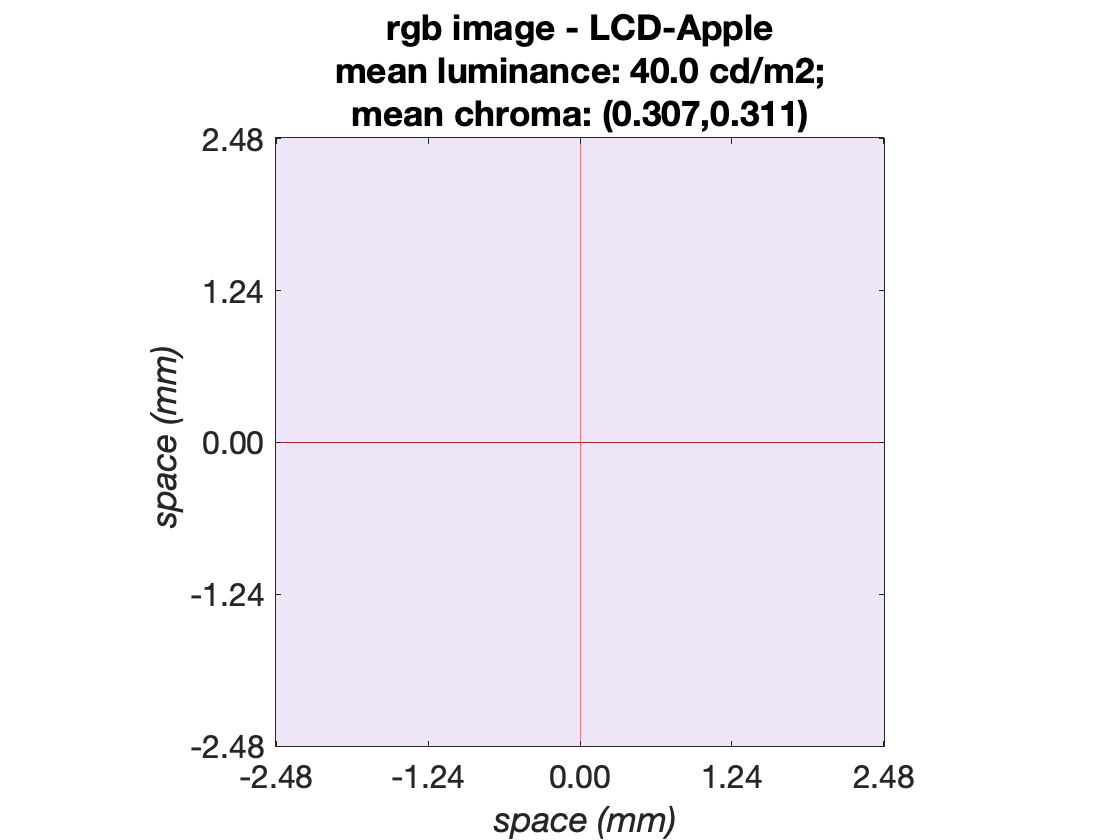

%% zero contrast for the null stimulus 
stimParams.contrast = 0.0;

% Generate a scene representing the 10% Gabor stimulus as realized on the presentationDisplay
nullScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize the generated scene
visualizeScene(nullScene, ...
    'displayRadianceMaps', false);

# **Step 4.** Compute the optical images of the 2 scenes

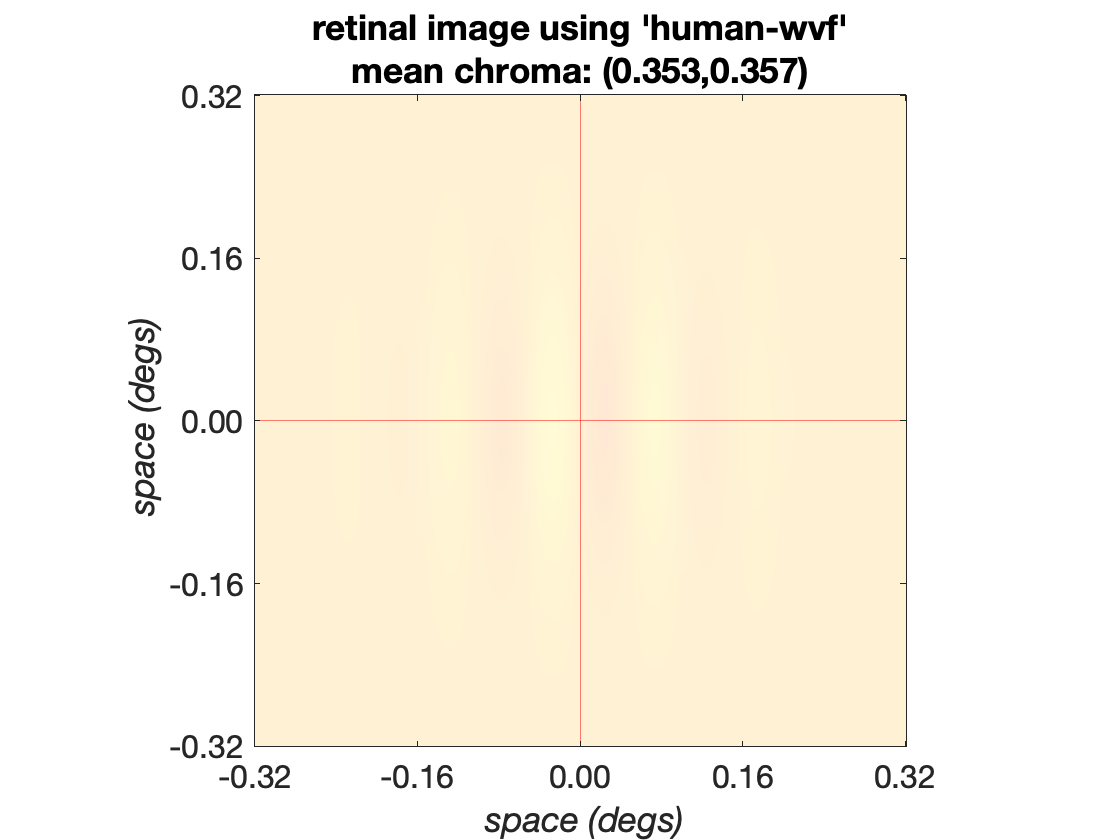

%% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

%% Compute the retinal image of the test stimulus
theTestOI = oiCompute(theOI, testScene);

%% Compute the retinal image of the null stimulus
theNullOI = oiCompute(theOI, nullScene);

%% Visualize the optical image of the test
visualizeOpticalImage(theTestOI, ...
    'displayRadianceMaps', false);

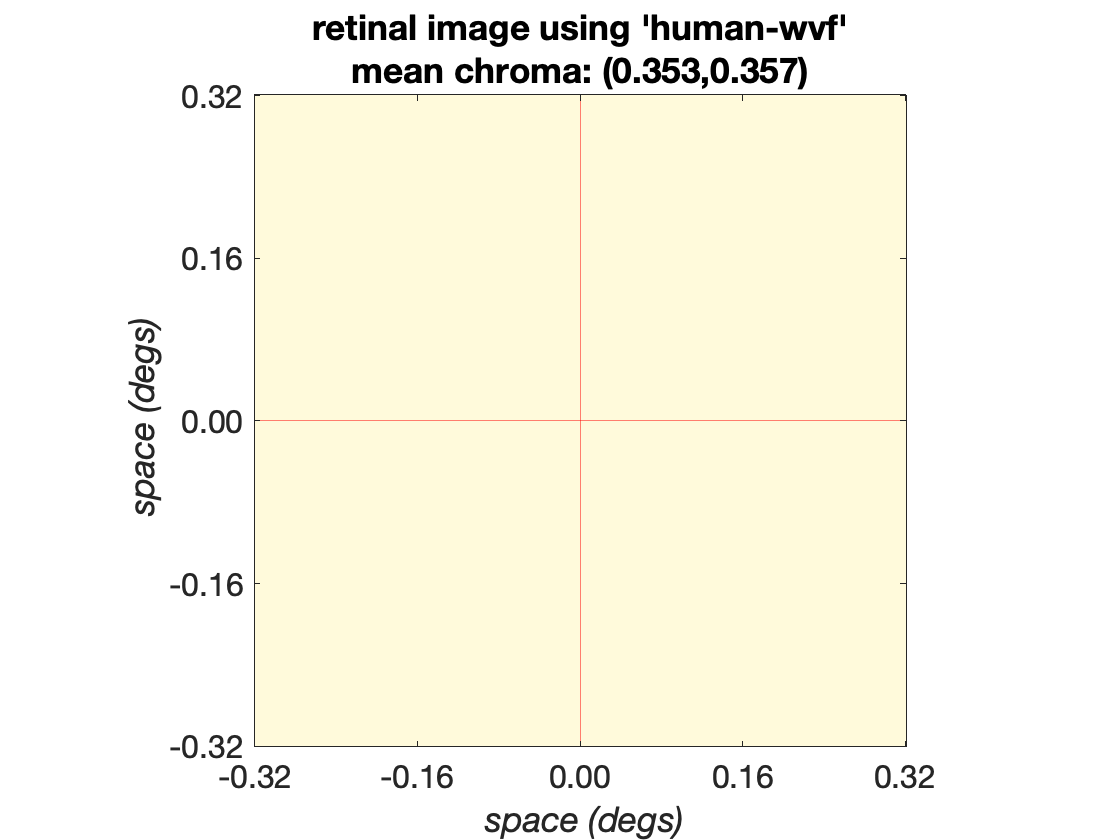


%% Visualize the optical image of the test
visualizeOpticalImage(theNullOI, ...
    'displayRadianceMaps', false);

# **Step 5.** Create a cone mosaic object

%% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(5, ...              % hex lattice sampling factor
   'fovDegs', stimParams.sizeDegs, ...        % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...           % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ... % cone quantal efficiency varies with eccentricity
   'integrationTime', 100/1000, ...           % 100 msec integration time
   'maxGridAdjustmentIterations', 50);        % terminate iterative lattice adjustment after 50 iterations

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid adjustment: on iteration 11 ... 
Hex grid adjustment: on iteration 12 ... 
Hex grid adjustment: on iteration 13 ... 
Hex grid adjustment: on iteration 14 ... 
Hex grid adjustment: on iteration 15 ... 
Hex grid adjustment: on iteration 16 ... 
Hex grid adjustment: on iteration 17 ... 
Hex grid adjustment: on iteration 18 ... 
Hex grid adjustment: on iteration 19 ... 
Hex grid adjustment: on iteration 20 ... 
Hex grid adjustment: on iteration 21 ...

# **Step 6a.** Compute 500 instances of mosaic responses to both the test and the null stimuli

% Generate 100 instances of zero movement eye movement paths
nTrialsNum = 100;
emPathLength = 1;
emPath = zeros(nTrialsNum, emPathLength, 2);

% Compute mosaic excitation responses to the test stimulus
coneExcitationsTest = theMosaic.compute(theTestOI, 'emPath', emPath);

% Compute mosaic excitation responses to the null stimulus
coneExcitationsNull = theMosaic.compute(theNullOI, 'emPath', emPath);

# **Step 6b.** Visualize the test and null stimulus responses

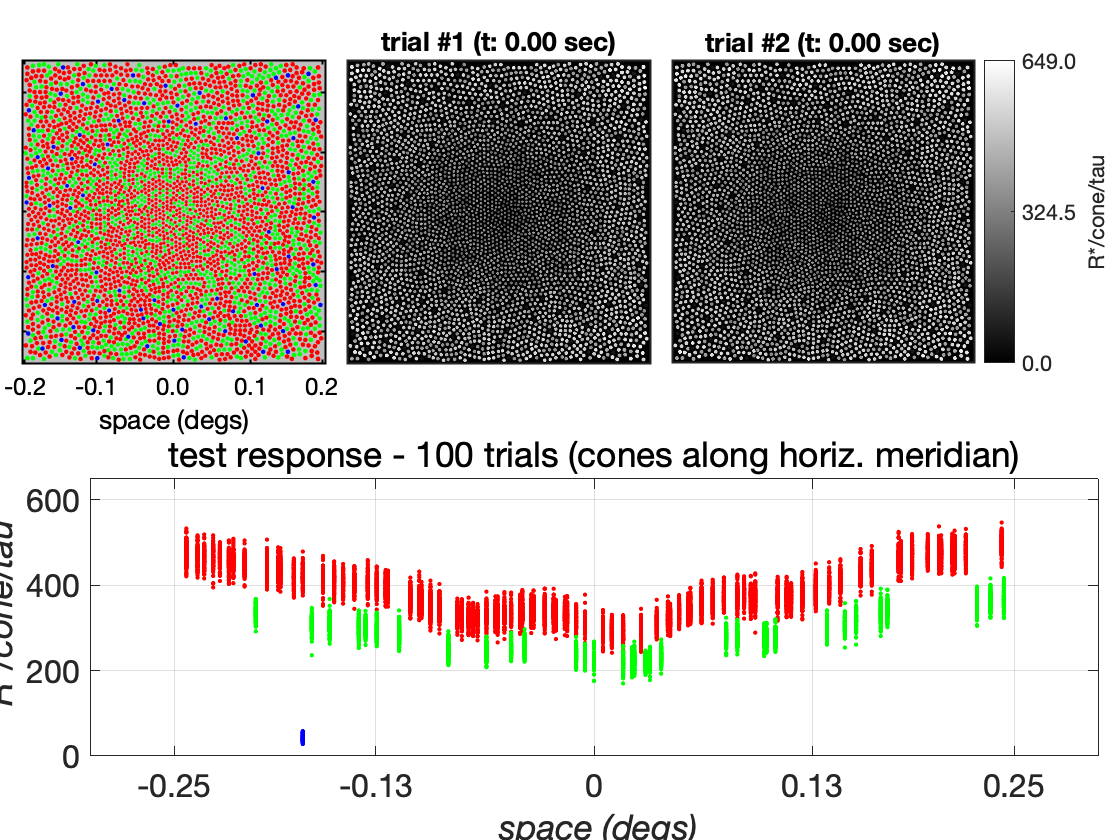

%% Visualize cone mosaic and its cone excitation responses to the test stimulus
visualizeConeMosaicResponses(theMosaic, coneExcitationsTest, ...
    'R*/cone/tau', ...
    'customTitle', 'test response');

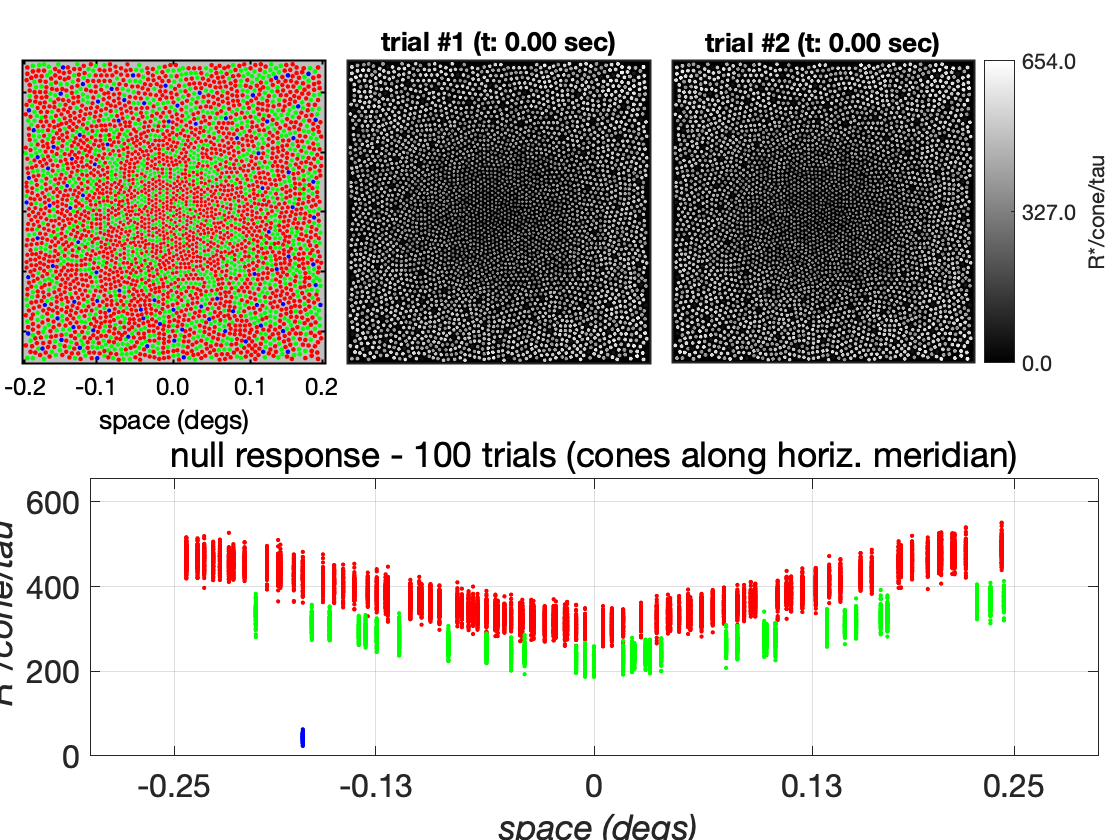


%% Visualize cone mosaic and its cone excitation responses to the null stimulus
visualizeConeMosaicResponses(theMosaic, coneExcitationsNull, ...
    'R*/cone/tau', ...
    'customTitle', 'null response');